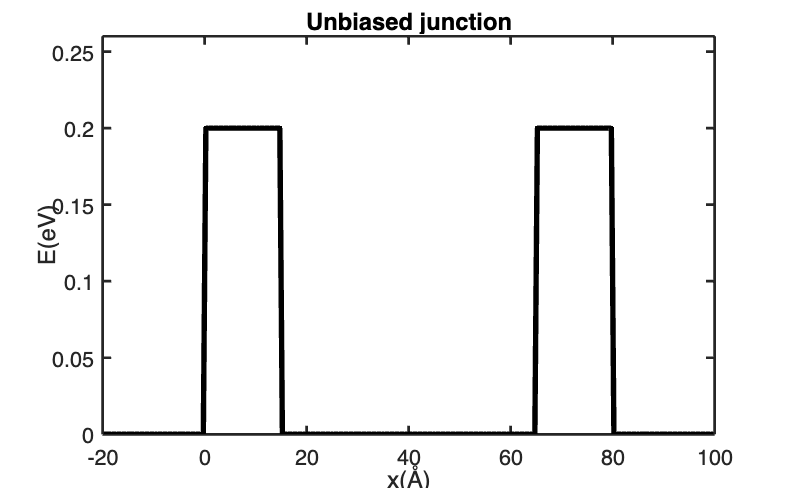

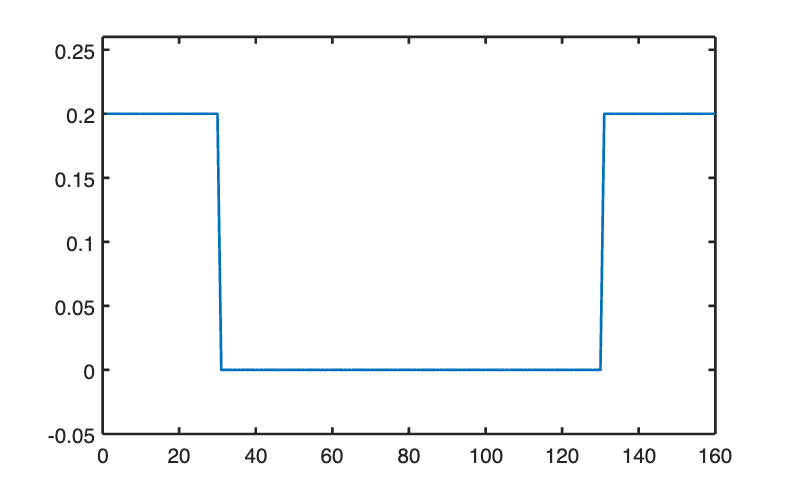

xin =    0.250000000000000   0.750000000000000   1.250000000000000   1.750000000000000   2.250000000000000   2.750000000000000   3.250000000000000   3.750000000000000   4.250000000000000   4.750000000000000   5.250000000000000   5.750000000000000   6.250000000000000   6.750000000000000   7.250000000000000   7.750000000000000   8.250000000000000   8.750000000000000   9.250000000000000   9.750000000000000  10.250000000000000  10.750000000000000  11.250000000000000  11.750000000000000  12.250000000000000  12.750000000000000  13.250000000000000  13.750000000000000  14.250000000000000  14.750000000000000  15.250000000000000  15.750000000000000  16.250000000000000  16.750000000000000  17.250000000000000  17.750000000000000  18.250000000000000  18.750000000000000  19.250000000000000  19.750000000000000  20.250000000000000  20.750000000000000  21.250000000000000  21.750000000000000  22.250000000000000  22.750000000000000  23.250000000000000  23.750000000000000  24.250000000000000  24.750000000

clear
mystartdefaults

%% Controls
potentialplot=true;        %Plot of the potential energy for the unbiased  junction
reftrabarrier=true;        %R-T-A plot for Equal barriers and constant background
wavefuncts=true;           %Resonant and a non-resonant wavefunctions plots
reftrabiasedbarrier=true;  %R-T-A plot for Different barriers and constnat background
biasedjunctionplot=true;   %Potential energy profile for the biased junction using a step as background
wavelengths=true;          %Calculate minimum and maximum wavelengths on both sides
reftrastep=true;           %R-T-A plot for step of -0.1eV
twostepsplot=true;         %Profiles  for the limits of the varying biased junction
varyingstep=true;          %R-T-A plot for varying step

recipunit=1.0E+10;
powee=1E-3;
ekinscale=(hbar*recipunit)^2/(2*elm)/qel;
dx= 0.5; % discretization of horizontal position
xmin=-20; %lower bound
xmax=100; %upper bound
xpmin=0; %lower bound  of the perturbated region
xpmax=80; %upper bound of the perturbated region
bar1=15; %position of the end of the first barrier
bar2=65; %position of the beggining of the second barrier
u1=0.2; %heights of barriers
u2=0.1;
step=-0.1; % Potential bias (for the second part)
dE=0.0005; %discretization of energy steps
Emax=0.3; %Upper bound for incoming energy
Emin=0.00; %lower bound for incoming energy
liftim=1.0E-9; % Lifetime
gam=(hbar*2*pi/liftim)/qel; % damping factor
stepmin=-0.2; %Lower bound for energy bias
stepmax=0.2; %Upper bound for energy bias

%% Setting up the x grid and the two equal height barriers
piecesin=round((xpmax-xpmin)/dx);
for ii=1:piecesin
    xin(ii) = dx/2+xpmin+(ii-1)*dx; %positions inside the perturbated zone
end
piecesL=round((xpmin-xmin)/dx);
for ii=1:piecesL
    xL(ii) = dx/2+xmin+(ii-1)*dx; %positions to the left
end
piecesR=round((xmax-xpmax)/dx);
for ii=1:piecesR
    xR(ii) = dx/2+xpmax+(ii-1)*dx; %positions to the right
end
x=[xL xin xR]; %all positions
Vbar=barriers(xin,bar1,bar2,u1,u1); %potential with two equal height barriers inside
Vbartot=[zeros(1,piecesL) Vbar zeros(1,piecesR)];

%% Plot of the potential energy for the unbiased  junction
if(potentialplot)
figure
plot(x,Vbartot,"black",'LineWidth',3);
title('Unbiased junction',"fontsize", 16);
ylabel('E(eV)');
xlabel('x(Å)');
ylim([0,0.26]);
end

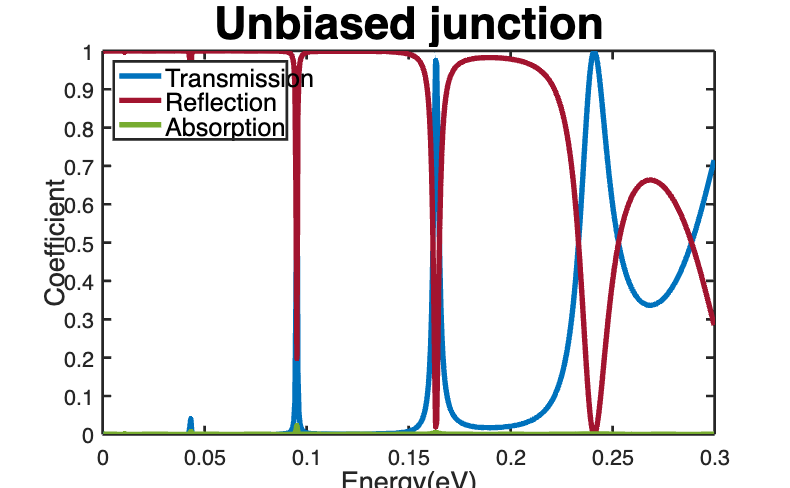

edivs=round((Emax-Emin)/dE);
for ii=1:edivs
  Eners(ii) =dE/2 +Emin+(ii-1) * dE; %Energy range we´ll look at
end

%% R-T-A plot for Equal barriers and constant background
if(reftrabarrier) 
for ii=1:edivs
    [Reff(ii),Traa(ii),absor(ii)]=spectra(0,Eners(ii),gam,xin,Vbar,dx,ekinscale) ; % the step is set to 0 to look at the constant background case
end
compalabel{1}=sprintf('Transmission');
compalabel{2}=sprintf('Reflection');
compalabel{3}=sprintf('Absorption');
figure
plot(Eners,Traa, Eners, Reff,Eners,absor,'LineWidth',3);
xlabel('Energy(eV)',"fontsize", 15);
ylabel('Coefficient',"fontsize", 15);
title('Unbiased junction',"fontsize", 25);
legend(compalabel,"fontsize",14,"location",'northwest');
end

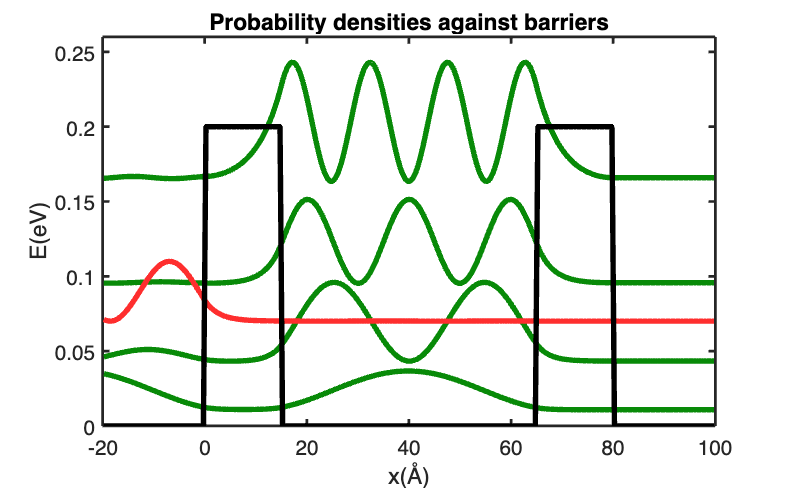

%% Wavefunctions of resonant and a non resonant energy
if(wavefuncts)
resoener=[0.01075,0.04325,0.09525,0.16325,0.07]; %Resonance energies found by looking at the R-T-A graph AND a non resonat enegry(the last one)
[~,nreso]=size(resoener);
wavefunctions=zeros(nreso,piecesL+piecesin+piecesR);
Wmat=zeros(piecesin,piecesin);
wavefunctions=zeros(nreso-1,piecesL+piecesin+piecesR);
for ii=1:nreso
    k1=sqrt((resoener(ii)+1i*gam)/ekinscale);
    for jj=1:piecesin
        phiok(jj)=exp(1i*k1*xin(jj)); % Unperturbed function to the right of the step [A.65]
        Wmat(jj,jj)=dx*Vbar(jj)/ekinscale; % Equation[4.39]
        for kk=1:piecesin
            Go(jj,kk)= Greenf(0,xin(jj),xin(kk),resoener(ii),gam,ekinscale); % Filling the green's function matrix (Equation [4.39])
        end
   end
   scatt=eye(piecesin)-Go*Wmat;
   phisol=scatt\(phiok.'); 
    for jj=1:(piecesL+piecesin+piecesR)
        if(ii<nreso) % Resonant wavefunctions
            wavefunctions(ii,jj)=exp((x(jj))*1i*k1)+outside_sol(x(jj),xin,Vbar,dx,phisol,0,resoener(ii),gam,ekinscale); % Unperturbed + scattered solution(Equation [4.36])
        else % Non-resonant wavefunction
            nonresophi(jj)=exp((x(jj))*1i*k1)+outside_sol(x(jj),xin,Vbar,dx,phisol,0,resoener(ii),gam,ekinscale); % Unperturbed + scattered solution(Equation [4.36])
        end
    end
end
resoprobas=abs(wavefunctions).^2; %probability densities
nonresoproba=abs(nonresophi).^2;

%Manually setting the aesthetics of the plots(consequence of comparing things with different units, but it's just for illustration purposes)
for jj=1:piecesL+piecesin+piecesR    
  resoprobas(1,jj)= 0.0065*resoprobas(1,jj)+resoener(1);
  resoprobas(2,jj)= 0.002*resoprobas(2,jj)+resoener(2);
  resoprobas(3,jj)= 0.0005*resoprobas(3,jj)+resoener(3);
  resoprobas(4,jj)= 0.0027*resoprobas(4,jj)+resoener(4); 
  nonresoproba(jj)= 0.01*nonresoproba(jj)+resoener(nreso);
end

figure
plot(x,resoprobas,'Color','#088A08','LineWidth',3); hold on;
plot(x,nonresoproba,'Color','#FE2E2E','LineWidth',3); hold on;
plot(x,Vbartot,"black",'LineWidth',3);
title('Probability densities against barriers','FontSize',20);
ylim([0,0.26]);
xlabel('x(Å)');
ylabel('E(eV)'); 
end

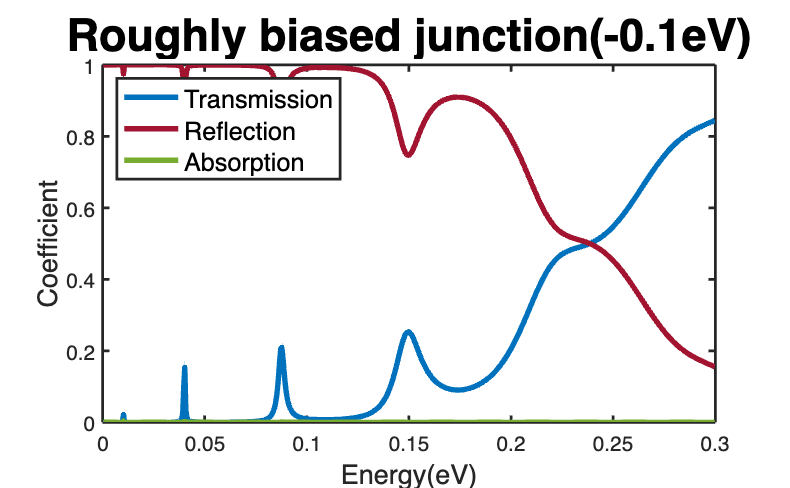

%% R-T-A plot for Different barriers and constnat background
if(reftrabiasedbarrier) 
Vbiased=barriers(xin,bar1,bar2,u1,u2);
for ii=1:edivs
    [Reff(ii),Traa(ii),absor(ii)]=spectra(0,Eners(ii),gam,xin,Vbiased,dx,ekinscale) ; % the step is set to 0 to look at the constant background case
end
compalabel{1}=sprintf('Transmission');
compalabel{2}=sprintf('Reflection');
compalabel{3}=sprintf('Absorption');
figure
plot(Eners,Traa, Eners, Reff,Eners,absor,'LineWidth',3);
xlabel('Energy(eV)',"fontsize", 15);
ylabel('Coefficient',"fontsize", 15);
title('Roughly biased junction(-0.1eV)',"fontsize", 25);
legend(compalabel,"fontsize",14,"location",'northwest');
end

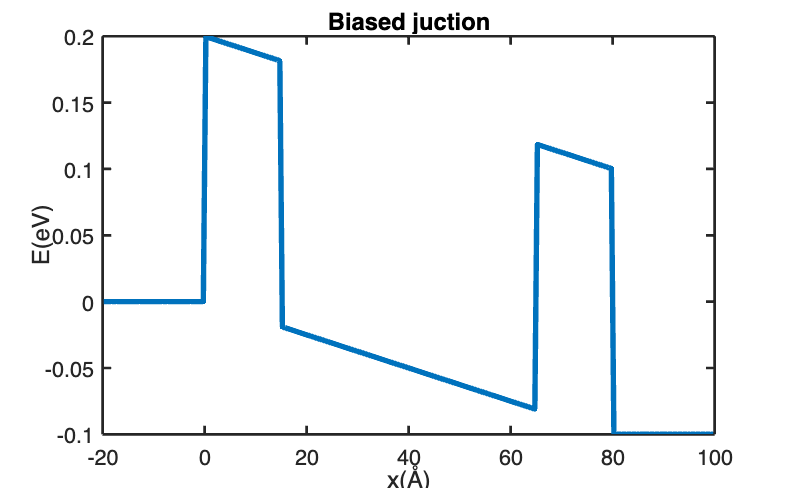

%% Creating the potential for the biased junction
for ii=1:piecesin
    efield(ii)=step*xin(ii)/(xpmax-xpmin);%-step; %Taking the reference
end
steppot=Vbar+efield;
for ii=1:piecesR
    Vright(ii)=step;
end
Vbartotstep=[zeros(1,piecesL) steppot Vright];

%% Potential energy profile for the biased junction using a step as background
if(biasedjunctionplot) 
figure
plot(x,Vbartotstep,'LineWidth',3);
title('Biased juction',"fontsize", 16);
ylabel('E(eV)');
xlabel('x(Å)');
end

%% Taking the step as a reference(IMPORTANT!)
for ii=1:piecesin
    steppot(ii)=steppot(ii)-step; 
end
%% Calculate minimum and maximum wavelengths on both sides
if(wavelengths)
    k0m=real(sqrt((Emin+1i*gam)*2*elm*qel/hbar^2));       % Dispersion relation for the left media [A.58]
    k0M=real(sqrt((Emax+1i*gam)*2*elm*qel/hbar^2));
    k1m=real(sqrt((Emin-step+1i*gam)*2*elm*qel/hbar^2));  % Dispersion relation for the right media [A.58]
    k1M=real(sqrt((Emax-step+1i*gam)*2*elm*qel/hbar^2));

    L0m= 2*pi*(1E+10)/k0M;
    L0M= 2*pi*(1E+10)/k0m;
    L1m= 2*pi*(1E+10)/k1M;
    L1M= 2*pi*(1E+10)/k1m;

    fprintf('Longest left wavelenght= %#5.5G [Å]\n', L0M);
    fprintf('Shortest left wavelenght= %#5.5G [Å]\n', L0m);
    fprintf('Longest right wavelenght= %#5.5G [Å]\n', L1M);
    fprintf('Shortest right wavelenght= %#5.5G [Å]\n', L1m);
end

Longest left wavelenght= 8528.7 [Å]


Shortest left wavelenght= 22.391 [Å]


Longest right wavelenght= 38.783 [Å]


Shortest right wavelenght= 19.391 [Å]


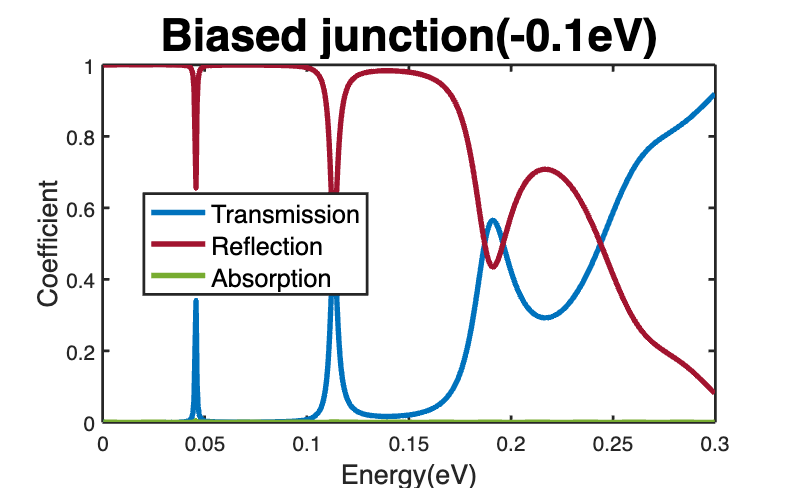

%% R-T-A plot for step of -0.1eV
if(reftrastep) 
for ii=1:edivs
    [Reff(ii),Traa(ii),absor(ii)]=spectra(step,Eners(ii),gam,xin,steppot,dx,ekinscale) ; 
end
compalabel{1}=sprintf('Transmission');
compalabel{2}=sprintf('Reflection');
compalabel{3}=sprintf('Absorption');

figure
plot(Eners,Traa, Eners, Reff,Eners,absor,'LineWidth',3);

xlabel('Energy(eV)',"fontsize", 15);
ylabel('Coefficient',"fontsize", 15);
title('Biased junction(-0.1eV)',"fontsize", 25);
legend(compalabel,"fontsize",14,"location",'best');
end

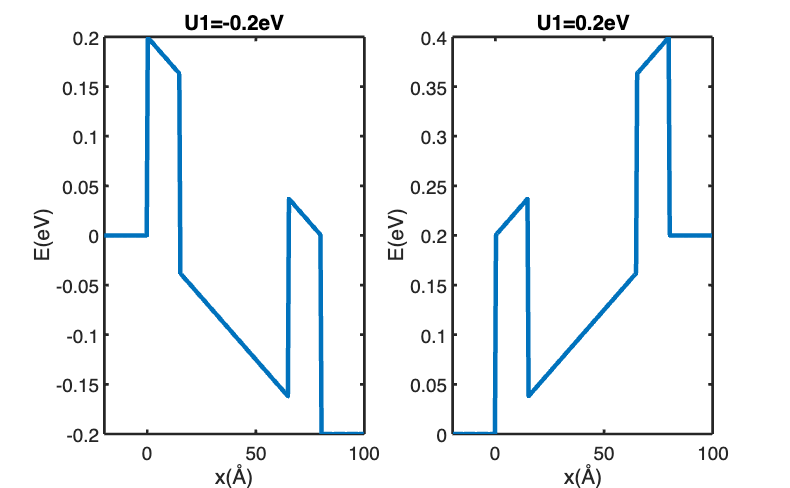

%% Profiles  for the limits of the varying biased junction
if(twostepsplot) 
for ii=1:piecesin
    efield1(ii)=stepmin*xin(ii)/(xpmax-xpmin);
    efield2(ii)=stepmax*xin(ii)/(xpmax-xpmin);
end
steppot1=Vbar+efield1;
steppot2=Vbar+efield2;
for ii=1:piecesR
    Vright1(ii)=stepmin;
    Vright2(ii)=stepmax;
end
Vbartotstep1=[zeros(1,piecesL) steppot1 Vright1];
Vbartotstep2=[zeros(1,piecesL) steppot2 Vright2];
figure
subplot(1,2,1)
plot(x,Vbartotstep1, "LineWidth",2.5);
title('U1=-0.2eV',"fontsize", 16);
ylabel('E(eV)');
xlabel('x(Å)');

subplot(1,2,2)
plot(x,Vbartotstep2, "LineWidth",2.5);
title('U1=0.2eV',"fontsize", 16);
ylabel('E(eV)');
xlabel('x(Å)');
end

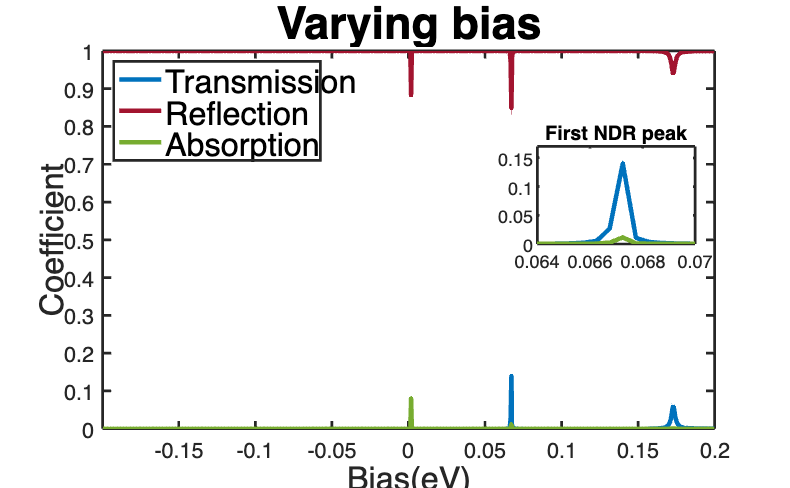

%% R-T-A plot for varying step
if(varyingstep) 

fixedE=0.01; % We fix this energy for the incoming  electron

edivs=round((stepmax-stepmin)/dE);
for ii=1:edivs
  Enerstep(ii) = dE/2 + stepmin+(ii-1)*dE; 
end

for ii=1:edivs
    for jj=1:piecesin
    efield(jj)=Enerstep(ii)*xin(jj)/(xpmax-xpmin)-Enerstep(ii); % The previous is to take the step as a reference
    end
    steppot=Vbar+efield;
    [Reff(ii),Traa(ii),absor(ii)]=spectra(Enerstep(ii),fixedE,gam,xin,steppot,dx,ekinscale) ; 
end

compalabel{1}=sprintf('Transmission');
compalabel{2}=sprintf('Reflection');
compalabel{3}=sprintf('Absorption');
figure
plot(-Enerstep,Traa, -Enerstep, Reff,-Enerstep,absor,"LineWidth",2.5); % The minus sign is added because we calculated using the electron's potential, but now we want to make an analysis on the current

xlabel('Bias(eV)',"fontsize", 18);
ylabel('Coefficient',"fontsize", 18);
title('Varying bias',"fontsize", 25);
legend(compalabel,"fontsize",18,"location",'northwest');
hold on;

ax=axes; % Inset plot zooming on the first NDR peak
set(ax,'units','normalized','position',[0.68,0.5,0.2,0.2]);
box(ax,'on');
plot(-Enerstep,Traa, -Enerstep, Reff,-Enerstep,absor,"LineWidth",2.5,'parent',ax);
title('First NDR peak',"fontsize", 20);
set(ax,'xlim',[0.064,0.07],'ylim',[0.0,0.17]); %'xlim',[0.065,0.07]
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% FUNCTIONS %%


%% GREEN'S FUNCTION

function [Gf]= Greenf(step,x,xp,E,gam,ekinscale) 
    ko=sqrt((E+1i*gam)/ekinscale);
    k1=sqrt((E+1i*gam-step)/ekinscale);
    if(x>=0 && xp>=0)
        Gf=exp(1i*k1*abs(x-xp))/(2i*k1) +  exp(1i*k1*(x+xp))*((k1-ko)/(k1+ko))/(2i*k1); % Green's function [A.76] for both positions greater than 0
    end

    if (x<0 && xp>=0)
        Gf=exp(-1i*ko*x+1i*k1*xp)/(1i*(ko+k1)); % Green's function [A.77] for x and xp  on different sides
    end
    if (xp<0 && x>=0)
        Gf=exp(-1i*ko*xp+1i*k1*x)/(1i*(ko+k1)); % Green's function [A.77] for xp and x  on different sides
    end
end

%% The extra part added to the solution due to the potential 
function[extra]= outside_sol(x,pos,V,dx,phisol,step,E,gam,ekinscale)
    extra=0;
    [~,nco]=size(pos);
    for ii=1:nco
        extra=extra+Greenf(step,x,pos(ii),E,gam,ekinscale)*dx*(V(ii)/ekinscale)*phisol(ii); %equation [4.36]
    end
end

%% Reflection, transmission and absorption coefficients
function[refl,tra,absor] = spectra(step,E,gam,pos,V,dx,ekinscale)
   [~,nco]=size(pos);
   ko=sqrt((E+1i*gam)/ekinscale);
   k1=sqrt((E+1i*gam-step)/ekinscale); 
   tb=2*ko/(ko+k1);
   rb=(ko-k1)/(k1+ko);
   Wmat=zeros(nco,nco);
   for ii=1:nco
    phiok(ii)=tb*exp(1i*k1*pos(ii));% Function to the right of the step [A.65]
    Wmat(ii,ii)=dx*V(ii)/ekinscale; % Equation[4.39]
    for jj=1:nco
        Go(ii,jj)= Greenf(step,pos(ii),pos(jj),E,gam,ekinscale); %Equation [4.39]
    end
   end
   scatt=eye(nco)-Go*Wmat;
   phisol=scatt\(phiok.'); % Solution inside the perturbated region [4.51]
   
   phirefl=rb*exp(-1i*ko*(pos(1)-1))+outside_sol(pos(1)-1,pos,V,dx,phisol,step,E,gam,ekinscale); %The first part comes from a pre-existing reflection in equation [A.65]
   phitrans=tb*exp(1i*k1*(pos(nco)+1))+outside_sol(pos(nco)+1,pos,V,dx,phisol,step,E,gam,ekinscale); %The first part comes from an already exinsting transmission in equation [A.65]
   
   tra=(real(k1)/real(ko))*abs(phitrans)^2;
   refl=(abs(phirefl/(exp(1i*ko*(pos(1)-1)))))^2; %comparing the reflected part with just an incoming wave
   absor=1-(refl+tra);
end

%% Barrier potential
function Vbbar =barriers(pos,bar1,bar2,u1,u2)
    [~,nco]=size(pos);
    Vbar=zeros(1,nco);
    for ii=1:nco
        if(pos(ii)<=bar1)
            Vbar(ii)=u1;  
        elseif(bar2<=pos(ii))
            Vbar(ii)=u2;   
        end
    end    
    Vbbar=Vbar;
end